# **Ejercicio 2**

## T2.2 Método de Ridder

### 28-02-2023

#### Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, 

####                 Melani Tatayo Culchas, Rubén Sierra Serrano.

a) Escribe una función de Matlab que emplee el método de Ridder para buscar la  raíz de una función en un intervalo. Nómbrala: $function   [r, i] = ridder(fun, x1, x2, tol) $ donde:

$fun =$ función en forma anónima $fun = @(x) $

$\left(x_1 ,\;x_2 \right)=$ intervalo donde se encuentra la raíz.

$tol =$ tolerancia calculada como $|\;x_i -x_{i-1} \;|$

$i =$ número de iteraciones

$r = $ raíz encontrada.

-Véase ridder.m

b) Se desea calcular la raíz de la función: 


$$f\left(x\right)=\frac{1}{{\left(x-0\ldotp 3\right)}^2 +0\ldotp 01}-\frac{1}{{\left(x-0\ldotp 8\right)}^2 +0\ldotp 04}$$


Declaramos la función.

clear, clc  % Limpieza del workspace y salidas
f = @(x) 1 ./ ((x-0.3).^2 + 0.01) - 1 ./ ((x-0.8).^2 + 0.04);

b.1) Dibuja la función en las proximidades de  $x=0$ para determinar el intervalo  aproximado $\left(x_1 ,{\;x}_2 \right)$ donde se encuentra la raíz. 

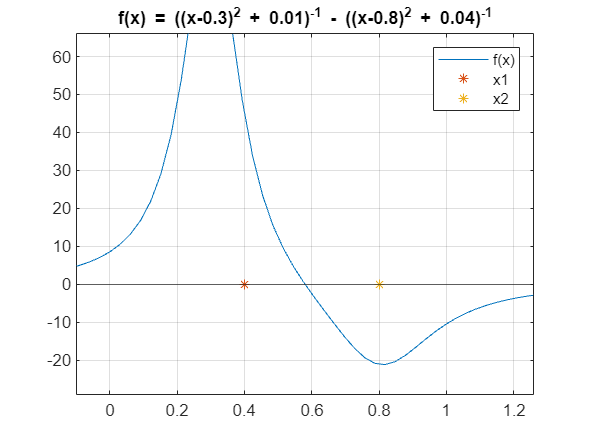

x = linspace(-1, 2);
pf = plot(x, f(x));
title("f(x) = ((x-0.3)^2 + 0.01)^{-1} - ((x-0.8)^2 + 0.04)^{-1}");
hold on
px1 = plot(0.4,0, "*");
px2 = plot(0.8,0, "*");

yline(0)
xlim([-0.10 1.26])
ylim([-29 66])

legend([pf px1 px2], ["f(x)" "x1" "x2"])
grid
hold off

Tomamos el intervalo $\left(x_1 ,{\;x}_2 \right)=\left(0\ldotp 4,\;0\ldotp 8\right)$  al que pertenece la raíz.

x1 = 0.4; x2 = 0.8;

b.2) Calcula la raíz empleando la función del apartado a) con un error menor que ${10}^{-6}$. Indica también el número de iteraciones empleadas.

ermax = 1e-6;
[r, i] = ridder(f, x1, x2, ermax);
fprintf("La raíz es %.6f", r);

La raíz es 0.580000

fprintf("Se han requerido %d iteraciones", i);

Se han requerido 7 iteraciones

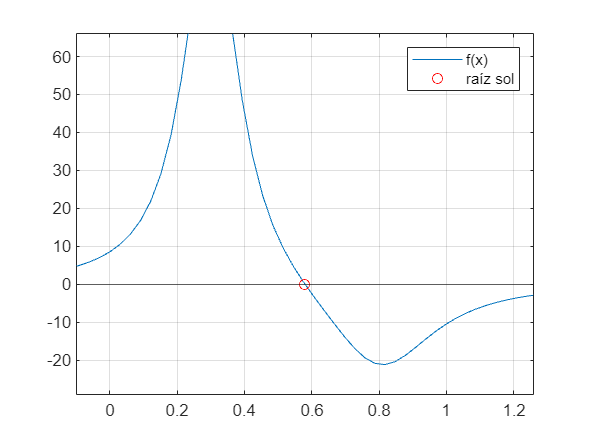

pf2 = plot(x, f(x));
hold on
pr = plot(r, f(r), 'ro');

yline(0)
xlim([-0.10 1.26])
ylim([-29 66])
legend([pf2 pr], ["f(x)" "raíz sol"]);
grid
hold off